% Time vector for input rf volt and drift
t1 = 0:0.00001:0.008;   

% RF characteristics
A1 = 1;                % Amplitude 1 
f1 = 1 / 0.002;         % Frequency: 1 cycle in 0.002 sec
omega1 = 2 * pi * f1;

% drift characteristics
A2 = 0.2;              % Amplitude 0.02
f2 = 1 / 0.008;         % Frequency: 1 cycle in 0.008 sec
omega2 = 2 * pi * f2;

% modulating rf voltag
Vin = A1 * sin(omega1 * t1);

% drit voltage
Vdrift = A2 * sin(omega2 * t1);

%Powerbytwo=0.2 assuming power =0.4W
A = (0.2+0.2*sin((pi*Vin)/2 +Vdrift))

A =     0.2000    0.2102    0.2203    0.2304    0.2404    0.2502    0.2598    0.2693    0.2785    0.2874    0.2961    0.3044    0.3124    0.3201    0.3274    0.3344    0.3409    0.3471    0.3528    0.3582    0.3632    0.3678    0.3720    0.3759    0.3794    0.3825    0.3853    0.3878    0.3900    0.3920    0.3936    0.3950    0.3962    0.3972    0.3980    0.3986    0.3991    0.3995    0.3997    0.3999    0.4000    0.4000    0.4000    0.3999    0.3998    0.3998    0.3997    0.3996    0.3995    0.3994


B = (0.2-0.2*sin((pi*Vin)/2 +Vdrift))

B =     0.2000    0.1898    0.1797    0.1696    0.1596    0.1498    0.1402    0.1307    0.1215    0.1126    0.1039    0.0956    0.0876    0.0799    0.0726    0.0656    0.0591    0.0529    0.0472    0.0418    0.0368    0.0322    0.0280    0.0241    0.0206    0.0175    0.0147    0.0122    0.0100    0.0080    0.0064    0.0050    0.0038    0.0028    0.0020    0.0014    0.0009    0.0005    0.0003    0.0001    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006


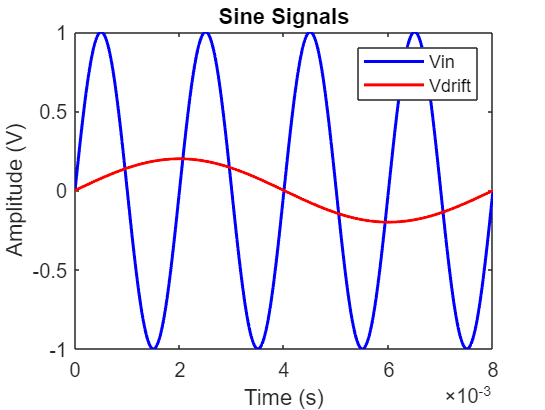


% Plotting the signals
plot(t1, Vin, 'b', 'LineWidth', 1.5);hold on;
plot(t1, Vdrift, 'r', 'LineWidth', 1.5);hold off;
title('Sine Signals');xlabel('Time (s)');ylabel('Amplitude (V)');legend('Vin', 'Vdrift');

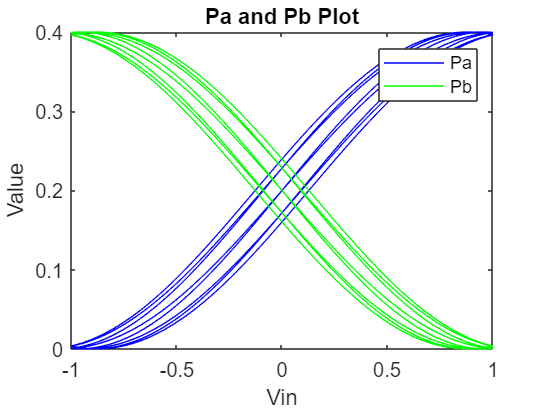


% Plot A and B
plot(Vin, A, 'b', 'LineWidth', 0.4);hold on;
plot(Vin, B, 'g', 'LineWidth', 0.4);hold off;
title('Pa and Pb Plot');xlabel('Vin');ylabel('Value');legend('Pa', 'Pb');


% Define the equations as a function
equations = @(x, A, B) [0.2 + 0.2*sin((pi/2)*x(1) + x(2)) - A; 0.2 - 0.2*sin((pi/2)*x(1) + x(2)) - B];

% initial guesses for Vin and Drift
initialGuess = [0;0];  

% Array of values for A and B
A_values = A;
B_values = B;

% Initialize arrays to store Vin and Vdrift values
Vin_values = zeros(801, 1);
Drift_values = zeros(801, 1);

% Run the loop for different values of A and B
for i = 1:801
    % Retrieve values for A and B from the arrays
    A = A_values(i);
    B = B_values(i);
    
    solution = fsolve(@(x) equations(x, A, B), initialGuess);
    
    % Extract the values of V and D from the solution
    Vin_values(i) = solution(1);
    Drift_values(i) = solution(2);
end


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 


 %Display the results
disp('Vin and Drift values for different combinations of A and B:');

Vin and Drift values for different combinations of A and B:


disp('---');

---


for i = 1:801
   disp(['Combination ' num2str(i) ': Vin = ' num2str(Vin_values(i)) ', Drift = ' num2str(Drift_values(i))]);
end

Combination 1: Vin = 0, Drift = 0
Combination 2: Vin = 0.023063, Drift = 0.014683
Combination 3: Vin = 0.046105, Drift = 0.029351
Combination 4: Vin = 0.069102, Drift = 0.043992
Combination 5: Vin = 0.092033, Drift = 0.05859
Combination 6: Vin = 0.11488, Drift = 0.073132
Combination 7: Vin = 0.14364, Drift = 0.078123
Combination 8: Vin = 0.16021, Drift = 0.10199
Combination 9: Vin = 0.17779, Drift = 0.12393
Combination 10: Vin = 0.20493, Drift = 0.13046
Combination 11: Vin = 0.22701, Drift = 0.14452
Combination 12: Vin = 0.26185, Drift = 0.13804
Combination 13: Vin = 0.27056, Drift = 0.17208
Combination 14: Vin = 0.29184, Drift = 0.18579
Combination 15: Vin = 0.31293, Drift = 0.19922
Combination 16: Vin = 0.3453, Drift = 0.19424
Combination 17: Vin = 0.36787, Drift = 0.20395
Combination 18: Vin = 0.42112, Drift = 0.16472
Combination 19: Vin = 0.40122, Drift = 0.2396
Combination 20: Vin = 0.56073, Drift = 0.031867
Combination 21: Vin = 0.43244, Drift = 0.2753
Combination 22: Vin = 0.635

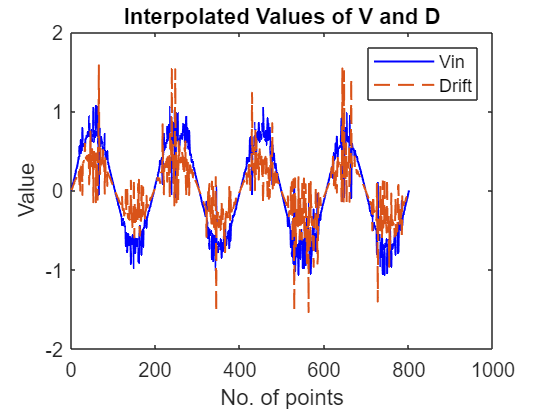


% Interpolate the values of V and D
t_interp = linspace(1, 801, 801);  % Time points for interpolation
V_interp = interp1(1:801, Vin_values, t_interp, 'spline');  % Interpolated values of V
D_interp = interp1(1:801, Drift_values, t_interp, 'spline');  % Interpolated values of D

% Plot the graph
figure;
plot(t_interp, V_interp, 'b', 'LineWidth', 1);hold on;
plot(t_interp, D_interp,'--', 'LineWidth', 1);hold off;
xlabel('No. of points');ylabel('Value');legend('Vin', 'Drift');title('Interpolated Values of V and D');


% Display the results
disp('Interpolated values of Vin and Drift:');

Interpolated values of Vin and Drift:


disp(['Time points: ' num2str(t_interp)]);

Time points: 1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49   50   51   52   53   54   55   56   57   58   59   60   61   62   63   64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127  128  129  130  131  132  133  134  135  136  137  138  139  140  141  142  143  144  145  146  147  148  149  150  151  152  153  154  155  156  157  158  159  160  161  162  163  164  165  166  167  168  169  170  171  172  173  174  175  176  177  178  179  180  181  182  183  184  185  186  187  188  189  190  191  192  193  194  195  196  197  198 

disp(['Vin: ' num2str(V_interp)]);

Vin: 0    0.023063    0.046105    0.069102    0.092033     0.11488     0.14364     0.16021     0.17779     0.20493     0.22701     0.26185     0.27056     0.29184     0.31293      0.3453     0.36787     0.42112     0.40122     0.56073     0.43244      0.6358     0.46917     0.49122     0.50958     0.50404     0.79168     0.56094     0.57957     0.58268     0.59382     0.59183     0.49972      0.6411     0.65418     0.65625     0.69252     0.67126     0.68815     0.74125     0.71437     0.68696     0.93624     0.70494     0.84697     0.49279     0.70854     0.70475     0.75952     0.62034     0.70442     0.68188      1.0455     0.61365     0.68035     0.75093     0.71063     0.67043      1.0692     0.69694     0.74098     0.69015      1.0602     0.59868      0.5731   -0.053244     0.55337     0.67177     0.77664     0.55486     0.67417     0.65522     0.59684     0.59412     0.61166      0.4519     0.45016     0.54179     0.50569     0.71309     0.40317     0.49943     0.45012     0.427

disp(['Drift: ' num2str(D_interp)]);

Drift: 0    0.014683    0.029351    0.043992     0.05859    0.073132    0.078123     0.10199     0.12393     0.13046     0.14452     0.13804     0.17208     0.18579     0.19922     0.19424     0.20395     0.16472      0.2396    0.031867      0.2753  -0.0031163     0.29868     0.30312     0.31232     0.35799   -0.057956     0.33923     0.34351     0.37107     0.38472     0.41775     0.59104     0.39626     0.40161     0.42279     0.38849     0.44447     0.43809     0.37238     0.42728     0.47452    0.078577     0.43288     0.19969     0.74654     0.39939     0.39852     0.30718     0.52204     0.38773     0.42248    -0.14786     0.53295     0.43216     0.32677     0.39706     0.46861    -0.14817     0.44659     0.38608     0.46952    -0.11686     0.59487     0.61721      1.5809     0.60561     0.39706     0.20806     0.53074     0.31632      0.3178     0.37996     0.35353     0.29402     0.51197     0.48058     0.30145     0.32193    -0.04108     0.40755     0.21724     0.25471     0.2